## **Polynomiální regrese gradientní metodou největšího spádu:**

Výchozí materiál: An overview of gradient descent optimization algorithms

Metoda největšího spádu je iterační metoda a její myšlenka je velmi prostá. Stejně jako v analitickém řešení polynomiální regrese, tak i zde řešíme skrze metodu nejmenších čtverců, tudíž zásislost kvadratického funkcionálu na zkoumané soustavě je vždy paraboloid. Hledání aproximace poté vlastně představuje hledání minimální hodnoty (v našem případě hodnoty koeficientů polynomu) tohoto paraboloidu, jinými slovy hledáme globální minimum této funkce. Jelikož se jedná o paraboloid, tak toto minimum lze nalézt pomocí gradientních metod. Gradientní metody obecně pracují následnovně. Je vybrán náhodný bod a je pro tento bod spočten gradient. Gradient ukazuje směr největšího růstu v daném bodě, tudíž záporný gradient ukazuje naopak směr největšího spádu. Můžeme tedy upravit hodnoty zkoumané soustavy (v našem případě koeficienty polynomu) ve směru gradientu a tím se přiblížit optimálnější aproximaci. Tyto kroky můžeme opakovat tak dlouho, dokud postupnými kroky nedojdeme až do minima funkce. Postup se snaží znázornit následující obrázek, kde černě jsou znázorněny vrstevnice paraboloidu a modře postupné kroky proti směru gradientu, kterými jsme dosáhli globálního minima této fuknce.

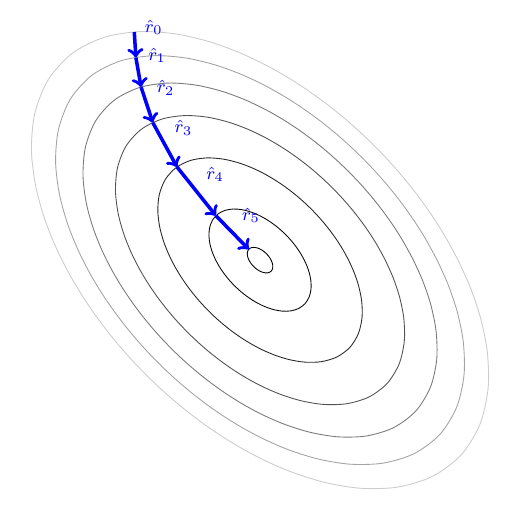

Tento postup může skýtat několik komplikací. Jednou z nich je otázka nastavení délky kroku, který děláme po výpočtu gradientu. Pokud bude krok moc dlouhý, je možné, že se budeme od optimálního řešení spíše vzdalovat a naopak pokud bude krok příliš krátký, bude trvat neúměrně dlouho, než do optima dojdeme. Stejně tak i problémem může být, pokud má paraboloid ošklivý tvar (uzký). Při takovém tvaru paraboliodu totiž neexistuje krok, který by směřoval přímo k minimu a dochází k tzv. cik cak efektu. Některé soustavy dokonce mohou mít závislost kvadratického funkcionálu takovou, že obsahují lokální minima, v takovém případě mohou gradientní metody naprosto selhat na nalezení optimální aproximace. Kvůli těmto problémům byla vyvinuta celá řada různých metod vylepšujících základní metodu největšího spádu.

Základní vzoreček vystihující metodu největšího spádu může vypadat např. takto: $w=w-\left(\eta \nabla f_{\left(\theta \right)} \right)\;$, kde $w$ jsou koeficienty polynomu, $\eta$ je učící faktor (délka kroku) a $\nabla f_{\left(\theta \right)}$ je gradient kvadratického funkcionálu zkoumané soustavy (to je ten paraboloid). 

Základní rozdělení metod největšího spádu může být podle toho, jaká tréninková data používá. V této funkci používám pouze tzv. Batch gradient descent (BGD -"Dávková" metoda největšího spádu), která se vyznačuje tím, že výpočet provádí na všech vstupních datech. Ale pokud bych měl vstupních dat příliš velké množství, mohu využít jiné varianty. Např. použít metodu Stochastic gradient descent (SGD - Náhodná metoda největšího spádu), která vybírá ze vstuních dat jen určitá za pomocí náhodného výběru a výpočet provádní na nich. Určitou střední cestou může být Mini batch gradient descent (mBGD - "Mini-dávková" metoda největšího spádu), která také používá jen určité vstupní data na základě náhodného výběru, ale místo jednotlivých vstupních dat si vybírá zhluky dat (skupiny sousedících), čímž se dosáhne zpravidla lepších výsledků, než u jednoduché SGD.

Dělení podle použitých tréninkových dat:

- BGD - Batch gradient descent

- SGD -  Stochastic gradient descent

- mBGD - Mini batch gradient descent

Kód níže ukazuje pouze základní metodu největšího spádu, ale mohl by obsahovat různá vylepšení. Např:

- Momentum - směr klesání není spočten pouze na základě gradientu v současném bodě, ale také podle gradientu v bodě předešlém. Díky tomu je možné eliminovat cik cak efekt. Na druhou stranu musím kromě délky kroku (učící faktor) vybrat také hodnotu, jak moc silný efek bude mít gradient v předešlém bodě na ten současný (typicky se značí $\lambda$)  

- RMSprop - změna parametru učení (délka kroku) na základě znaménka gradientu. Pokud se od posledního výpočtu znaménko gradientu změní, krok se zmenšuje, pokud se naopak zneménko změnilo, vypadá to, že se pohybuji kolem minima a tak krok změnším.

- ADAM - adaptivně mění délku kroku...  TODO

Např. vzoreček pro Momentum by vypadal $\theta =\theta -\left(\gamma \left(\eta \nabla f_{\left(\theta -1\right)} \right)+\eta \nabla f_{\left(\theta \right)} \right)\;$. Vzoreček je prakticky stejný jako pro obyčejnou metodu největšího spádu, jen nám zde přibyl člen $\gamma \left(\eta \nabla f_{\left(\theta -1\right)} \right)$. Tento člen obsahuje výpočet gradientu z předešlého kroku a přenásobuje ho určitým faktorem $\gamma$ (většinou hodnota 0.9 nebo tak nějak). Následně je tento člen přičten k výpočtu gradientu v součaném bodě a tím je deinován další bod $w$.

function [t_w,w_aprox,e,E_w,iter] = Batch_gradient_descent_symbolic(x, t, M, q, max_iter)
%   x:          vzorkovací čas
%   t:          naměřenné vzorky
%   M:          řád polynomu
%   q:          pokud přensot řešení bude menší než tato hodnota, řešení se vrací a metoda končí
%   max_iter    pokud se ani do tohoto počtu iterací nenajde řešení, metoda končí a vrací se poslední zjištěné řešení
%   t_w:        body aproximace pro vstupní hodnoty x
%   w_aprox:    koeficienty aproximačního polynomu
%   e:          rozdíl bodů aproximační funkce a naměřených výstupů
%   E_w:        velikost druhých mocnin rozdílů e (metoda nejmenších čtverců)


Do $N$je uložen počet vzorků. 

N = length(x);          % počet pozorování získaný z délky vektoru vstupních hodnot

Nyní proběhne příprava koeficientů v symbolické podobě. Budu totiž chtít spočítat gradient funkce bez toho, aniž bych měl vyčíslené koeficienty $w$, protože právě za koeficienty $w$ budu následně v iteracích dosazovat nově vypočtené hodnoty z iterace předešlé. Já totiž znám vstup $x$ a výstup $y$, a jediné co mi chybí jsou koeficienty $w$.  Počet symbolických proměných je tedy  závislý na řádu polynomu (každý řád polynomu musí mít vlastní koeficient, tudíž vlastní symbolickou proměnou).

syms w [1,M+1];                 % příprava koeficientů symbilicky (abych mohl spočítat obecný gradient funkce)
                                % dříve než budu koeficienty dosazovat, si spočítám gradient funkce, u které hledám minimum
                                % v našem případě to je funkce získaná metodou nejmenších čtverců. U této funkce budu hledat minimum na základně
                                % změny koeficientů, tzn. že budu parciálně derivovat tuto funkci každým koeficientem, čímž dostanu hodnotu
                                % obecně gradient funkce. Čili parciální derivace ve všech "směrech" koeficientů. Pokud tedy za koeficienty
                                % dosadím moje náhodné koeficienty, dostanu hodnotu jak moc a jakým směrem změnit tyto koeficienty, aby lépe
                                % aproximovali vstupní data.
                                
% Pokud bych si chtěl spočítat výstupní data pro náhodné koeficienty, popř. si z nich vykreslit graf nebo vypsat hodnotu MNČ: 
% t_aprox = Polynomial_evaluation(x,w_aprox); % vypočtení pro náhodný náhodný odhad koeficientů
% plot(x,t_aprox,'r') % zobrazení řešení pro náhodné koeficienty
% Least_squares_method(t_aprox,t);


Nyní dohází k vytvoření N polynomů o N neznámých, kde neznámé jsou koeficienty $w$. Zde vytvářím bázové funkce modelu, tedy vlastně říkám, že hledaná optimalizace bude polynomiální. Kdybych zde používal jiný předpis, mohl bych hledat optimalizaci pro kterékoliv jiné bzové funkce. 

### 
$$y_{\left(1\right)} ={w_1 {\;+\;w}_2 \cdot x_1 +w}_3 \cdot {x_1 }^2 +\ldotp \ldotp \ldotp +w_M \cdot {x_1 }^M$$


### 
$$y_{\left(2\right)} ={w_1 {\;+\;w}_2 \cdot x_2 +w}_3 \cdot {x_2 }^2 +\ldotp \ldotp \ldotp +w_M \cdot {x_2 }^M$$


### 
$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\vdots$$


### 
$$y_{\left(N\right)} ={w_1 {\;+\;w}_2 \cdot x_N +w}_3 \cdot {x_N }^2 +\ldotp \ldotp \ldotp +w_M \cdot {x_N }^M$$


y_w = sym(zeros(1,N));                          % příprava symbolických rovnic pro každý vstup
for i = 1:N                                     % pro každý vstup 
    for j = 0:M                                 % vypočítej přes daný řád polynomu
        y_w(i) = y_w(i) + ((w(j+1))*(x(i)^j));  % podle rovnice polynomu (x^j*w_j)
    end
end

Na symbolicky vyjádřených rovnicích je provedena metoda nejmenších čtverců, čili součet kvadrátů rozdílů aproximace a skutečných naměřených dat normovaný dvěmi. Z toho získám jednu rovnici o M počtu neznámých.

### 
$$E_w =\frac{1}{2}\left({\left(y_{\left(1\right)} -t\right)}^2 +{\left(y_{\left(2\right)} -t\right)}^2 +{\left(y_{\left(3\right)} -t\right)}^2 +\ldotp \ldotp \ldotp +{\left(y_{\left(N\right)} -t\right)}^2 \right)$$


E_w_sym = ((sum((y_w - t).^2))./2);               

Následuje ýpočet gradientu funkce $E_w$. Nejprve si připravím vektor symbolických rovnic. Počet rovnic je roven počtu řádu polynomu, jelikož do každé rovnice bude uložena parciální derivace podle jednoho z koeficientů. Jinými slovy derivuji rovnici $E_w$ podle $w_1$, potom $w_2$, potom $w_2$ tad..


$$\nabla E_w =\left(\frac{d}{\mathrm{d}w_1 }E_w ,\frac{d}{\mathrm{d}w_2 }E_w ,\frac{d}{\mathrm{d}w_3 }E_w ,\;\ldotp \ldotp \ldotp ,\frac{d}{\mathrm{d}w_M }E_w \right)$$
 

grad_sym = sym(zeros(1,M+1));
for i = 1:(M+1)                         % přes všechny koeficienty 
    grad_sym(i) = diff(E_w_sym,w(i));   % parciálně derivuj sumu nejmenších čtverců
end   

To znamená že jsem si připravil gradient ztrátové funkce, která má místo koeficientů symboly $w_i$ za které můžu dosazovat libovolné hodnoty. A já hledám takovou hodnotu, pro kterou je hodnota této ztrátové funkce minimální. Následující postup bude takový, že si pomocí vyjádřeného gradientu vypočítám přesné hodnoty gradientu pro všechny počáteční náhodné hodnoty koeficientů $w_i$. Následně tyto hodnoty přenásobím koeficientem učení a odčítám od počátečních náhodných koeficientů. Tím se vlastně částečně přiblížím s koeficienty k nižší hodnotě ztátové funkce $E_w$, čímž pádem koeficienty budou lépe aproximovat tréninková data. 

Zde tedy provádím první krok, a to vytvoření náhodných počátečních koeficientů.   

w_aprox = rand(M+1,1)*10;       % vytvoření náhodných koeficientů, ze kterých budu ve výpočtu vycházet a postupně je měnit

Zde už probíhá samotný cyklus popsaný o odstavec výše. Dosadím do rovnice gradientu:


$$\nabla E_w =\left(\frac{d}{\mathrm{d}w_1 }E_w ,\frac{d}{\mathrm{d}w_2 }E_w ,\frac{d}{\mathrm{d}w_3 }E_w ,\;\ldotp \ldotp \ldotp ,\frac{d}{\mathrm{d}w_M }E_w \right),\;\;w_i \;\epsilon \;R\;<0;10>$$
 

iter = max_iter;   % iter je proměnná, která vyjadřuje počet iterací, které bylo zapotřebí k výpočtu pro zadanou hodnotu tolerance (je nastavena na maximum, ale pokud se algoitmus dostane k tolaranci dříve, tato proměnná je přepsána)
for i = 1:max_iter % algoritmus tedy provádí cyklus, dokud nebylo tolerance menší než zadaná, nebo se nedosáhne maximální počtu iterací

    grad = double(subs(grad_sym,w,w_aprox'))';  % výpočet hodnoty gradientů podle jednotlivých koeficientů při současných koeficientech (náhodných, a v dalších iteracích upravené výpočtem) 
    w_aprox = w_aprox - (grad.*0.0000001);      % následně jsou vypočteny nové koeficienty tak, že od starých koeficientů odečtu hodnoty gradientu přenásobené koeficientem učení.
    t_w = Polynomial_evaluation(x,w_aprox);     % nyní vypočítám výstupní hodnoty pro vstupní hodnoty dosazené do polynomu s koeficienty, které jsme vypočítali výše 
    [E_w,e] = Least_squares_method(t_w,t);      % abych zjistil jak moc je moje nová aproximace přesné, vypočítám MNČ oproti původním vstupním datům
    
    if E_w < q          % hodnotu získanou MNČ porovnám s požadovanou tolerancí, a pokud byla požadovaná tolerance dosažena, tak mohu hodnotu koeficientů vrátit
        iter = i;
        break;
    end
end                    

Je tady ale jeden velký problém. konkrétně problém s tím, jak velký krok udělat (čili jak nastavit velký koeficient učení). Na to existuje několik způsobů, jak problém řešit (momentum (druhá derivace - hessián (Newtonova metoda)), RS prob, ADAM )